clc; clear; close all;
s = tf('s');

%% Constants
b = 0.26; % Wheelbase (meters)
T_s = 0.1;  % Sampling time (seconds)

%% Define Continuous Transfer Function
tau = 0.9; 
G_cont = 1 / (s * (tau * s + 1));  % More realistic model
G_cont

G_cont =
 
       1
  -----------
  0.9 s^2 + s
 
Continuous-time transfer function.
Model Properties


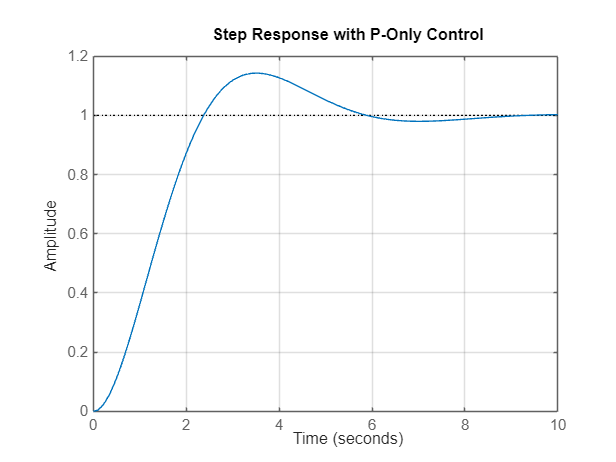



%% Initial Continuous PID Gains (Ziegler-Nichols or manual tuning)
Ku = 1; %Picked at random
C_p = pid(Ku, 0, 0);  % P-Only Controller
CL_p = feedback(C_p * G_cont, 1);  % Closed-loop system

figure(1);
step(CL_p);
title('Step Response with P-Only Control');
xlim([0 10])
grid on;

stepinfo(CL_p)

ans = struct with fields:
         RiseTime: 1.605937091556354
    TransientTime: 7.180772594039436
     SettlingTime: 7.180772594039436
      SettlingMin: 0.900922398068822
      SettlingMax: 1.142459501141632
        Overshoot: 14.245950114163207
       Undershoot: 0
             Peak: 1.142459501141632
         PeakTime: 3.481508660605606


## Ziegler-Nichols

[y, t] = step(CL_p);
A = y(end); % Steady-state value
threshold = 0.05 * A; % Define small threshold for delay detection

% Find time delay L (first noticeable increase)
L_idx = find(y > threshold, 1, 'first');


if isempty(L_idx)  % If no increase is detected, fallback to a small L
    L = T_s;  % Assume the delay is at least one sampling time
    warning('L could not be detected properly. Using L = T_s as a fallback.');
else
    L = t(L_idx);
end
 

% Find time constant tau (time at 63% of A)
tau_idx = find(y > 0.63 * A, 1, 'first');
tau = t(tau_idx) - L;

% Compute slope R
R = A / tau;

Kp = 1.2/(L*R);
Ki = 2*L;
Kd = 0.5*L;

C_zn = pid(Kp, Ki, Kd);  % PID-controller
CL_zn = feedback(C_zn * G_cont, 1);  % Closed-loop system
CL_zn

CL_zn =
 
      0.1658 s^2 + 4.188 s + 0.6631
  --------------------------------------
  0.9 s^3 + 1.166 s^2 + 4.188 s + 0.6631
 
Continuous-time transfer function.
Model Properties


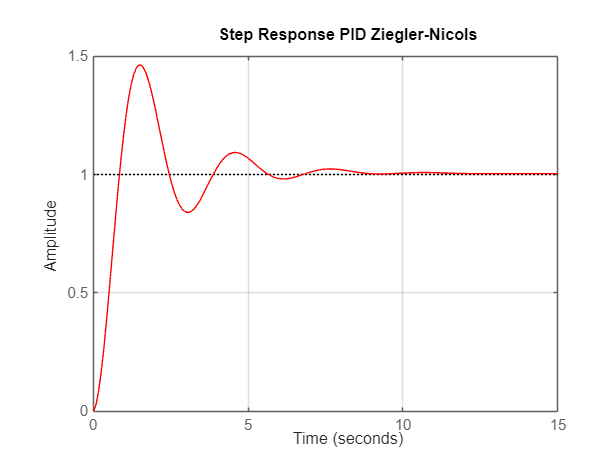


figure(2);
step(CL_zn,'r');
title('Step Response PID Ziegler-Nicols');
xlim([0 15])
grid on;

stepinfo(CL_zn)

ans = struct with fields:
         RiseTime: 0.587687969653383
    TransientTime: 8.013390329556021
     SettlingTime: 8.013390329556021
      SettlingMin: 0.840464023178985
      SettlingMax: 1.462312405314521
        Overshoot: 46.231240531452087
       Undershoot: 0
             Peak: 1.462312405314521
         PeakTime: 1.466665464907282



fprintf('Ziegler-Nichols PID Gains: Kp = %.5f, Ki = %.5f, Kd = %.5f\n', Kp, Ki, Kd);

Ziegler-Nichols PID Gains: Kp = 4.18792, Ki = 0.66314, Kd = 0.16579


Hand tuning:

Kp_h = Kp;
Ki_h = Ki;
Kd_h = Kd*20;

C_h = pid(Kp_h, Ki_h, Kd_h);  % PID-controller
CL_h = feedback(C_h * G_cont, 1);  % Closed-loop system
CL_h

CL_h =
 
       3.316 s^2 + 4.188 s + 0.6631
  --------------------------------------
  0.9 s^3 + 4.316 s^2 + 4.188 s + 0.6631
 
Continuous-time transfer function.
Model Properties


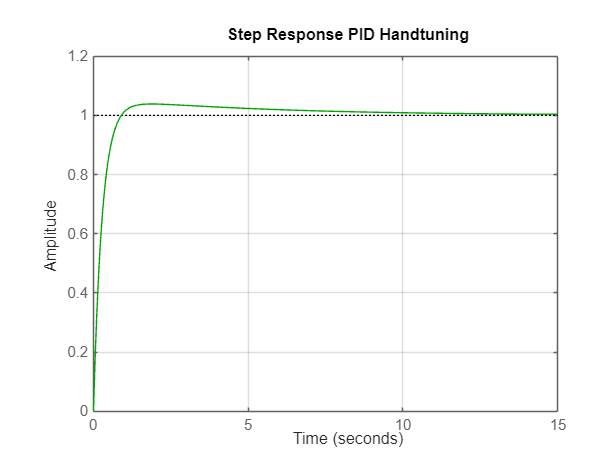


figure(3);
step(CL_h,'g');
title('Step Response PID Handtuning');
xlim([0 15])
grid on;

stepinfo(CL_h)

ans = struct with fields:
         RiseTime: 0.533790551931678
    TransientTime: 5.768360092310287
     SettlingTime: 5.768360092310287
      SettlingMin: 0.905053242656440
      SettlingMax: 1.038232510533683
        Overshoot: 3.823251053368337
       Undershoot: 0
             Peak: 1.038232510533683
         PeakTime: 1.873634077701970



fprintf('Ziegler-Nichols PID Gains: Kp = %.5f, Ki = %.5f, Kd = %.5f\n', Kp_h, Ki_h, Kd_h);

Ziegler-Nichols PID Gains: Kp = 4.18792, Ki = 0.66314, Kd = 3.31572


Discrete:

C_disc = c2d(C_h, T_s, 'tustin');  % Discretization using Tustin's method

% Display the discrete PID transfer function
disp('Discrete PID Controller:');

Discrete PID Controller:


C_disc

C_disc =
 
            Ts*(z+1)        2*(z-1) 
  Kp + Ki * -------- + Kd * --------
            2*(z-1)         Ts*(z+1)

  with Kp = 4.19, Ki = 0.663, Kd = 3.32, Ts = 0.1
 
Sample time: 0.1 seconds
Discrete-time PID controller in parallel form.
Model Properties


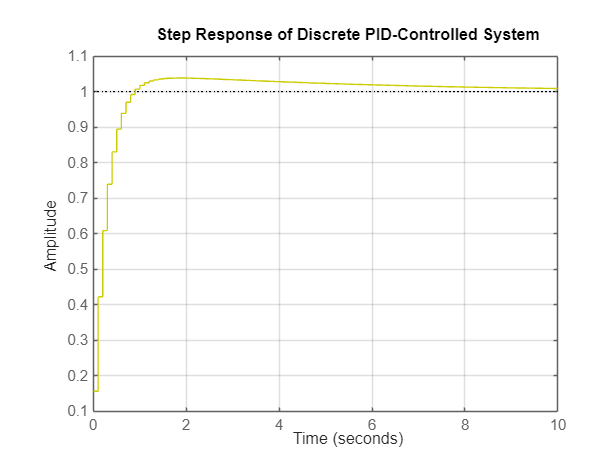


G_disc = c2d(G_cont, T_s, 'tustin'); % Discretize the plant as well
CL_disc = feedback(C_disc * G_disc, 1);

figure(4);
step(CL_disc,'y');
title('Step Response of Discrete PID-Controlled System');
xlim([0 10])
grid on;


pole(CL_disc)

ans =   -0.999999999999999
   0.980540066444415
   0.899390538200152
   0.699282331348320


All plots

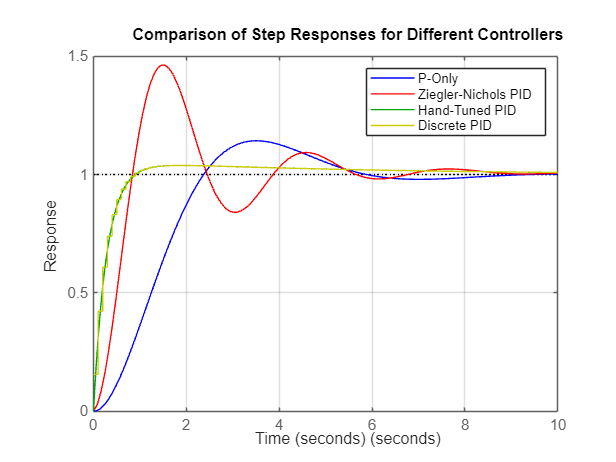

figure;
hold on;
step(CL_p, 'b'); % P-Only (Blue)
step(CL_zn, 'r'); % Ziegler-Nichols PID (Red)
step(CL_h, 'g'); % Hand-Tuned PID (Green)
step(CL_disc, 'y'); % Discrete PID (Yellow)
legend('P-Only', 'Ziegler-Nichols PID', 'Hand-Tuned PID', 'Discrete PID');
title('Comparison of Step Responses for Different Controllers');
xlabel('Time (seconds)');
ylabel('Response');
xlim([0 10])
grid on;
hold off;